# ROM Ph.D. Playground

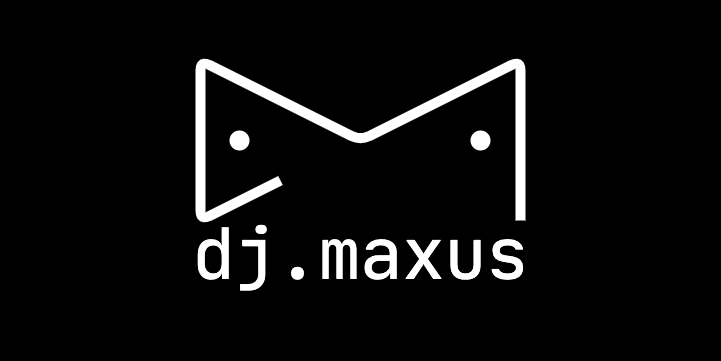

%% Analytical solution
% % generate linear matrix
% J = buildJacobian(zeros(Nx,2),1,problem.param);
% % u_t + Jx * u = q
% Jx = full([J.Jx,J.Jxb;zeros(2,Nx+2)]);
% % evaluate
% exact = problem.sol;
% X = calcGreenODE(Jx,[x0;bc.state(:,2)],problem.sol.t,-[problem.param.q.val;0;0]);
% exact.X = X(1:end-2,:);
% plotComp(exact, problem.sol, D, fig); fig;
%
% try DMDc
% X = exact.X;
% dX = diff(X,1,2)./dt;
% Q = repmat(-full(problem.param.q.val),1,Nt);
% [A,U,S] = dmds(X(:,2:end),dX-Q,23);
% dmded = problem.sol;
% dmded.X = calcGreenODE(-A,x0,problem.sol.t,-problem.param.q.val,23);
% dmded.X = real(dmded.X);
% plotComp(dmded, exact, D, fig); fig;

## Startup

startup;

## PDE Settings

- Dimensionality

Nx = 1000;

- Boundary Conditions

bc = genBC(1,[0,0]);

- Diffusion

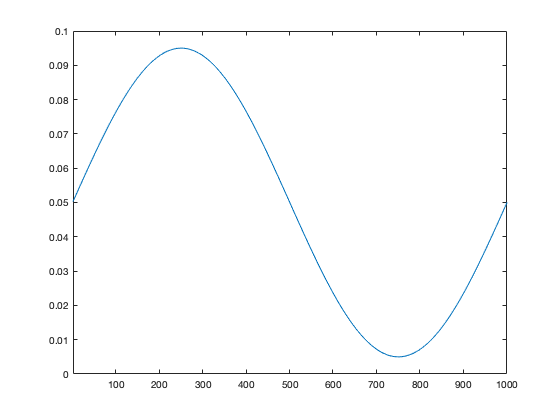

k = 0;
model = @(u) [1+u^2*k,2*u*k];
D  = genDiffusion(Nx,0.9,1,0.5e-1,model);
plot(1:(Nx+1),D.val);
xlim([1,Nx+1]);

- Initial Condition

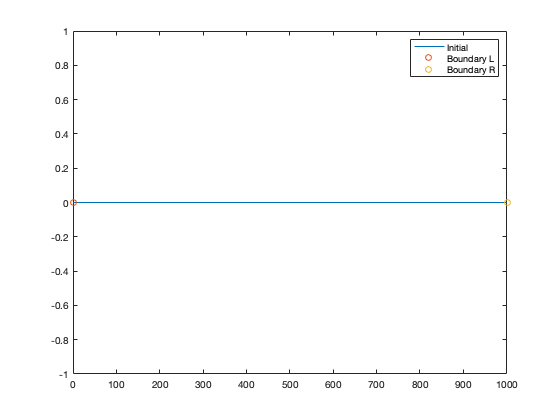

x0 = genInit(Nx,0,2,0);
plot(1:Nx,x0,'-',0,bc.val(1),'o',Nx+1,bc.val(2),'o');
xlim([0,Nx+1]);
legend({'Initial','Boundary L','Boundary R'});

Problem Constructors

- FOM

makeFOM = @(q,name) genProblem(name,Nx,genParam(D,bc,q),x0);

- ROM-I

makeROM_I = @(name,q,encoder) genProblem(name,Nx,genParam(D,bc,q),x0,encoder);

- ROM-II

makeROM_II = @(name,q,encoder,nfa) genProblem(name,Nx,genParam(D,bc,q),x0,encoder,nfa.res,nfa.jac);

## ODE settings

- Endtime $T$

T = 1;

- Number of timesteps $N_t$

Nt = 100;

- Timestep $\tau = \frac{T}{N_t}$

dt = T/Nt;

## Nonlinear  Solver Settings

- Convergence Criteria

newton_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 1e-3,...
    'tol_rel'  , 1e-3,...
    'tol_g'    , 1e-3,...
    'tol_rel_g', 1e-3 ...
    );

- Newton solver

nlin_newton = @(x,Res,Jac) newton      (x,Res,Jac,newton_param);

- Newton — Gauss solver

nlin_gauss  = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param);

## Train set

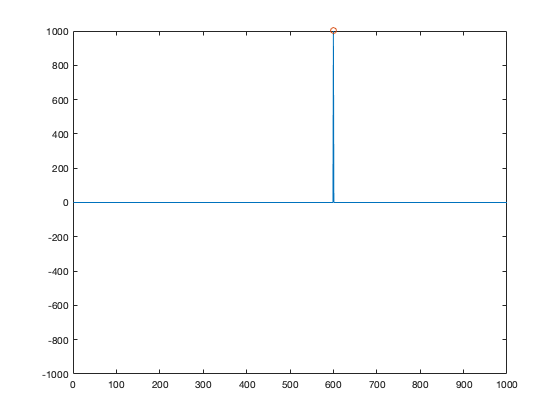

q = genSource(Nx,0.6,1e+3);
plot(axes(figure),1:Nx,q.val,'-',q.pos,q.val(q.pos),'o');
xlim([0,Nx]);
ylim([-sum(abs(q.val)),sum(abs(q.val))]);

### FOM

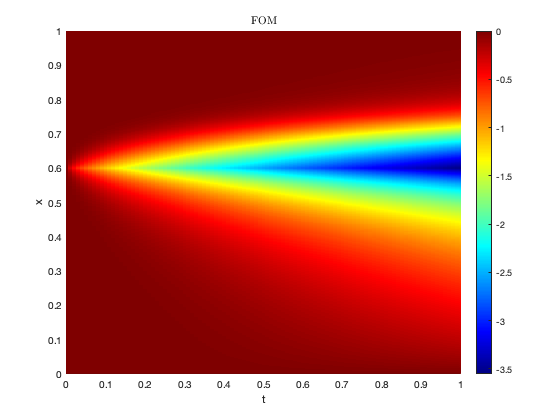

FOM = makeFOM(q,'FOM');
FOM = solveDif(T,Nt,FOM,nlin_newton);
plotSol(axes(figure),FOM);

### ROM

Collect Data

[X,W,Jw] = collectSolData(FOM);

#### POD

Train Encoder

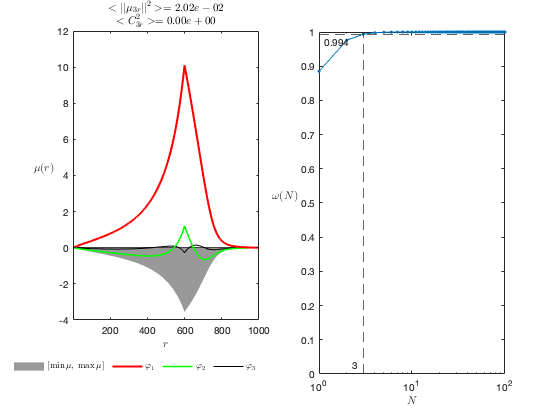

en_crit = 0.99;
pod = PCA(X, en_crit, 'init', x0);
pod.plotSummary(figure);

#### ROM-I

Perfom POD-ROM Calculation

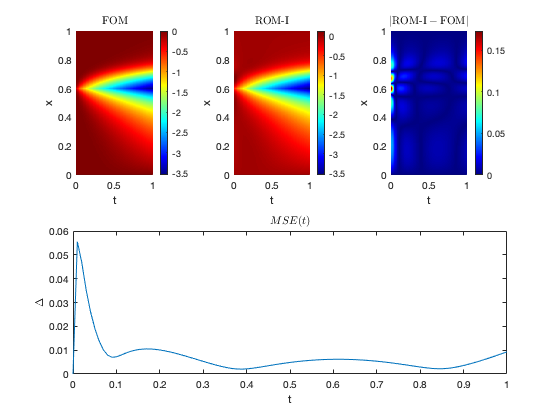

encoder = pod.genEncoder();

ROM.I = makeROM_I('ROM-I',q,encoder);
ROM.nlin = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param, encoder.decjac);

ROM.I = solveDif(T,Nt,ROM.I,ROM.nlin);
ROM.I.X = encoder.decode(ROM.I.X);
plotComp(figure(),FOM,ROM.I);

#### GAPPY-POD

POD for nonlinear functions

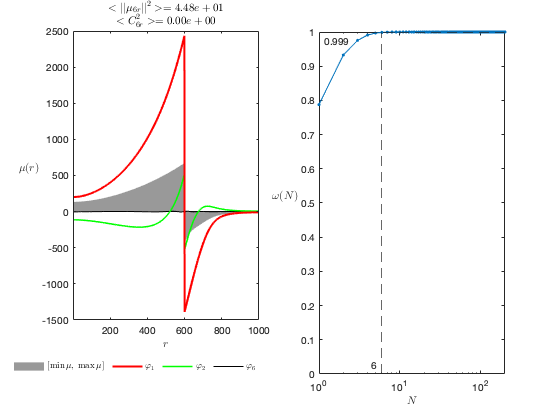

N1 = floor(pod.npc() * 2);
gappy.init = zeros(Nx+1,1);
gappy.R = PCA( W, N1,'init', gappy.init);
gappy.J = PCA(Jw, N1,'init', gappy.init);
gappy.R.plotSummary(figure);

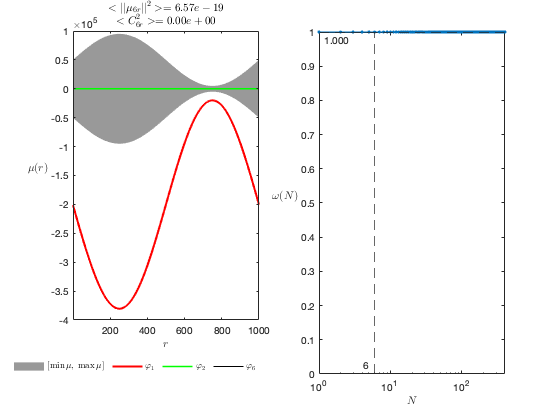

gappy.J.plotSummary(figure);

Gappy mask

N2 =floor(N1*2);
idx = unique([gappy.R.calcGreedy(N2),...
              gappy.J.calcGreedy(N2)]);
idx = unique([idx,1,Nx+1,q.pos]);
disp(idx);

  Columns 1 through 12

           1           2           3           4           5           6         202         209         210         212         216         218

  Columns 13 through 23

         250         251         445         446         563         564         599         600         612         613        1001



Gappy operators

gappy.R = gappy.R.buildGappy(idx);
gappy.J = gappy.J.buildGappy(idx);


Nonlinear Function Approximation

nfa.res = gappy.R.genNFA();
nfa.jac = gappy.J.genNFA();

#### ROM-II

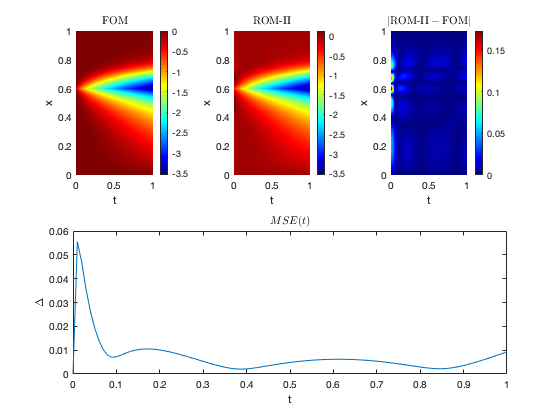

ROM.II = makeROM_II('ROM-II',q,encoder,nfa);
ROM.II = solveDif(T,Nt,ROM.II,ROM.nlin); % solve
ROM.II.X = encoder.decode(ROM.II.X); % decode solution
plotComp(figure,FOM,ROM.II);

## test set

test.q = genSource(Nx,0.55,1e+3);                       % specific property
% FOM
test.FOM = makeFOM(test.q,'test.FOM');          % setup
test.FOM.sol = solveDif(T,Nt,test.FOM,nlin_newton); % solve
plotComp(fig, train.FOM.sol, test.FOM.sol);                         % plot

Unrecognized function or variable 'fig'.

## ROM-I

Encoder


test.pod = PCA(test.FOM.sol.X,0.99,'init',x0,'sval_deg',1);
test.encoder = test.pod.genEncoder();
% Problem
test.ROM.I = makeROM_I('test.ROM-I',test.q,test.encoder);
test.ROM.nlin = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param,test.encoder.decjac);
% Solution
test.ROM.I.sol = solveDif(T,Nt,test.ROM.I,test.ROM.nlin); % solve
test.ROM.I.sol.X = test.encoder.decode(test.ROM.I.sol.X); % decode solution
plotComp(fig,test.FOM.sol,test.ROM.I.sol);                 % plot
% ROM-II

## Hypothesis

U1 = train.FOM.sol.X(:,2:end);
Phi1 = train.encoder.decjac(1);
C1 = U1 \ Phi1;

U2 = test.FOM.sol.X(:,2:end);
Phi2 = test.encoder.decjac(1);
C2 = U2 \ Phi2;

Phi3 = U2 * C1;
U3 = Phi3 * Phi3' * U2;

## ROM-I

Encoder

pod = PCA(U3,0.99,'init',x0,'sval_deg',1);
encoder = pod.genEncoder();
% Problem
ROM.I = makeROM_I('ROM-I',test.q,encoder);
ROM.nlin = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param, encoder.decjac);
% Solution
ROM.I.sol = solveDif(T,Nt,ROM.I,ROM.nlin); % solve
ROM.I.sol.X = encoder.decode(ROM.I.sol.X); % decode solution
plotComp(fig,test.ROM.I.sol,ROM.I.sol);                 % plot

## Comparison

plotComp(fig,train.FOM.sol,test.FOM.sol);

## Collect ROM data

function [X,W,Jw] = collectSolData(sol)
    X = sol.X;
    W = [sol.nlin.residual];
    W = [W.W];
    Jw = [sol.nlin.jacobian];
    Jw = [Jw.Jf];
end